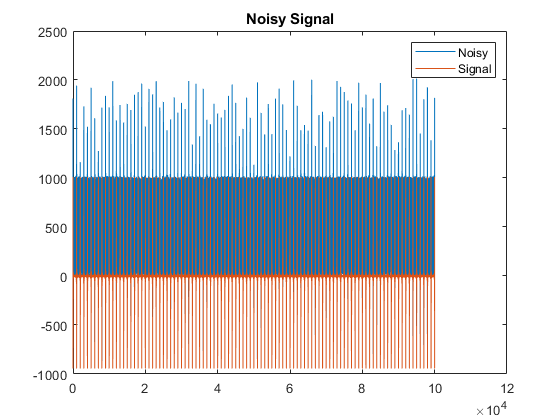

finalT = 100; %seconds
NumTimePts = 100000;
NFFT = 10000;

times = linspace(0, finalT, NumTimePts+1);%seconds
freqs = linspace(0,1000,NFFT+1);
Fs = 1 / (finalT/NumTimePts);

f = 250;%Sinewave Freq
Amp = 10;
s = zeros(1,length(times));
for i2 = 200:300
    s = s + Amp*cos(2*pi.*times*i2); %load (); %voice recording
end
    
An = max(s);%dB
noise = An*rand(1, length(s));
nSignal =  s + noise;

figure; plot(nSignal), hold on, plot(s);
legend("Noisy", "Signal");
title("Noisy Signal");

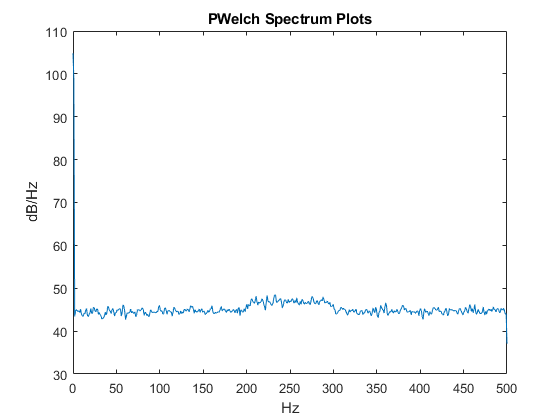

mag =    48.4799
   48.4234
   48.3183
   48.1545
   48.1109
   48.0013
   47.8848
   47.7947
   47.7892
   47.5749


ifreqs =    237
   238
   228
   215
   281
   294
   282
   236
   263
   244


%xlim([0 100])


NFFT = 1024;
HANN_SPECT = pwelch(nSignal, hanning(NFFT), (NFFT/2), NFFT, Fs);

figure;
freqs = linspace(0,Fs/2,length(HANN_SPECT));
HANN_SPECT_MAG = 20*log10(HANN_SPECT);
plot(freqs, HANN_SPECT_MAG);
title("PWelch Spectrum Plots");
xlabel("Hz"); ylabel("dB/Hz");

nSIGNAL = fft(nSignal);
mag_nSIGNAL = 20*log10(abs(nSIGNAL));
len = length(nSIGNAL);
freqs = linspace(0,Fs,len);
figure; plot(freqs(1:len/2), mag_nSIGNAL(1:len/2));

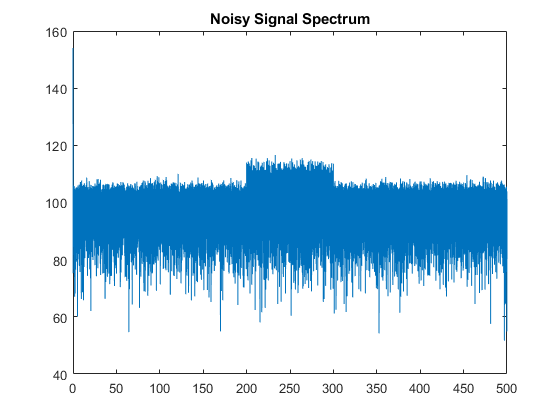

%plot(mag_nSIGNAL);
title("Noisy Signal Spectrum");





[mag, ifreqs] = maxk(HANN_SPECT_MAG(3:length(HANN_SPECT_MAG)), 10) %Assuming DC on index 1


ifreqs = sort(ifreqs, 'ascend');
fs_0 = linspace(0, freqs(min(ifreqs)), zero_pad_filt);
fs_1 = linspace(freqs(min(ifreqs)+1), freqs(max(ifreqs)-1), length(ifreqs));
fs_2 = linspace(freqs(max(ifreqs)), Fs/2, zero_pad_filt);

mag_0 = zeros(1, zero_pad_filt);
mag_1 = ones(1, length(ifreqs));
mag_2 = zeros(1, zero_pad_filt);

dFreqs = [fs_0, fs_1, fs_2]

dFreqs =          0    0.4280    0.8560    1.2840    1.7120    2.1400    2.1500    2.2356    2.3211    2.4067    2.4922    2.5778    2.6633    2.7489    2.8344    2.9200    2.9300  102.3440  201.7580  301.1720  400.5860  500.0000


dMag = [mag_0, mag_1, mag_2]

dMag =      0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0




%dFreqs = [0 20 50 100 150 200 250 300 350 400 450 500]; length(dFreqs)
%dMag = [0 0 1 1 1 1 1 1 0 0 0 0]; length(dMag)
dW = 2*dFreqs / Fs; length(dW)

ans = 22

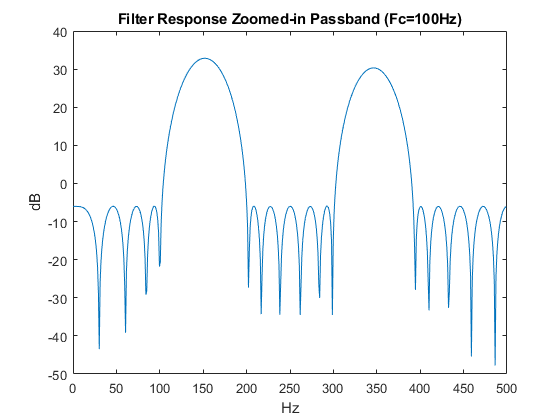


b = firpm(32,dW,dMag);%,w);

[H, freqs] = freqz(b, 1, 512, Fs);
figure; plot(freqs,20*log10(abs(H)));
title("Filter Response Zoomed-in Passband (Fc=100Hz)");
xlabel("Hz"); ylabel("dB");

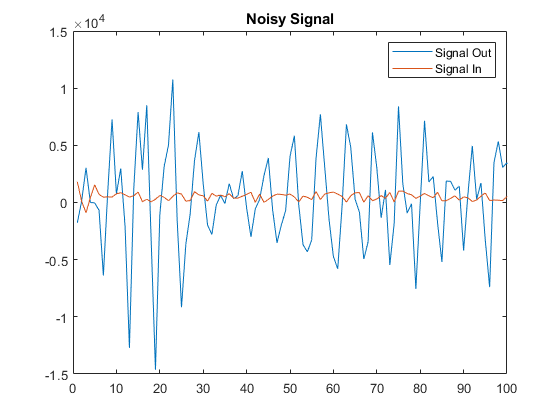


s_out = conv(b, nSignal);
SOUT = fft(s_out);
mag_SOUT = 20*log10(abs(SOUT));
len = length(SOUT);
freqs = linspace(0,Fs,len);

figure; plot(s_out), hold on, plot(nSignal);
legend("Signal Out", "Signal In");
title("Noisy Signal");
xlim([0 100])


figure; plot(freqs(1:len/2), mag_SOUT(1:len/2));

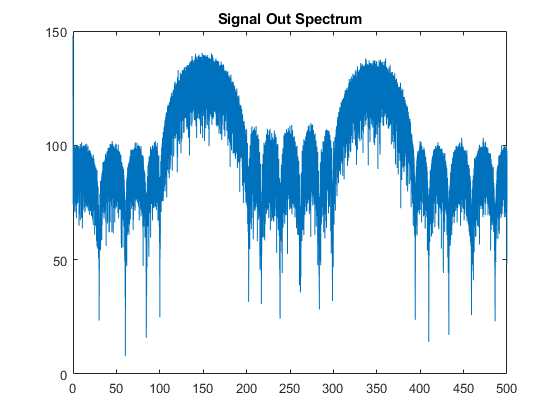

%plot(mag_nSIGNAL);
title("Signal Out Spectrum");